%reads the data from simulation
CL = load('Cylindrical_Results_Detailed')

CL =      Analytic: [1x996 double]
         CORE: {2x13 cell}
            L: 1
       MCarlo: [1x996 double]
            i: 13
         r2_L: [0.3000 0.4000 0.6000 0.8000 1 1.2500 1.5000 2 3 4 5 6 8]
    rangeL_r1: [1x996 double]
        total: 90000


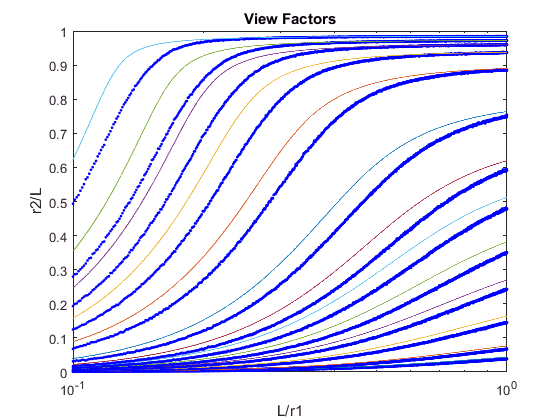

r2_L = CL.r2_L;
rangeL_r1 = CL.rangeL_r1;
h = figure('units','normalized','Name','View Factors','Position',[0.11201 0.2513 0.40996 0.54688]);
for i = 1:length(r2_L)
semilogx(CL.rangeL_r1,CL.CORE{1,i},'b.')
hold on
semilogx(CL.rangeL_r1,CL.CORE{2,i})
end
xlim([0.1,rangeL_r1(length(rangeL_r1))]);
xlabel('L/r1')
ylabel('r2/L')
title('View Factors')

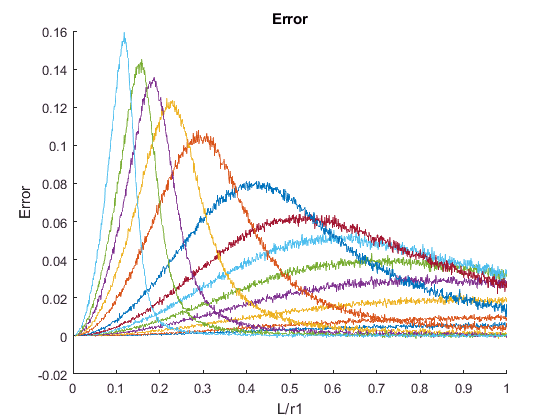

f = figure('units','pixels','Name','Error','position',[724 194 560 420]);
hold on
for i = 1:length(r2_L)    
    C = CL.CORE{2,i}-CL.CORE{1,i};
    Err(i,:) = [max(C),rangeL_r1(find(C == max(C))),r2_L(i)];
    plot(CL.rangeL_r1,C);
end
xlabel('L/r1')
ylabel('Error')
title('Error')

e1 = figure();
Q(:,1) = Err(:,1);
Q(:,2) = Err(:,3)./Err(:,2);
f2 = fit(Q(:,1),Q(:,2),'exp1')

f2 =      General model Exp1:
     f2(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1742  (0.1288, 0.2197)
       b =       37.33  (35.61, 39.05)

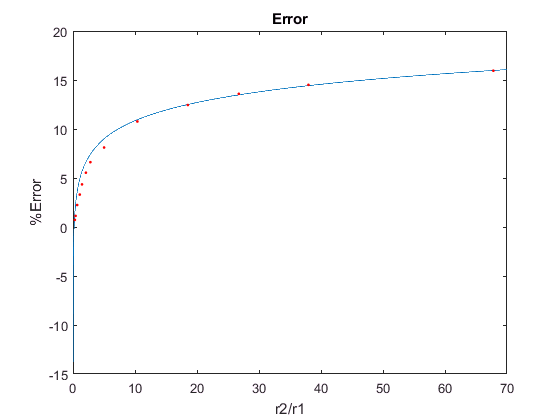

f1 = @(x)((log(x)-log(f2.a))/f2.b);
range = [0:0.001:70];
F = [range',f1(range)'];
plot(F(:,1),F(:,2)*100);
hold on
plot(Q(:,2),Q(:,1)*100,'r.');
hold off
xlabel('r2/r1')
ylabel('%Error')
title('Error')